X_trains = cell(4,1);
y_trains = cell(4,1);
n_els = [5, 10, 20, 100];
for i = 1:length(n_els)
   [X_trains{i}, y_trains{i}] = generate_data(n_els(i));
end 
[X_test, y_test] = generate_data(1000);

50 train klasa 1 50 train klasa 1

nets = cell(4,1)

nets = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for i = 1:4
    nets{i} = train_net(X_trains{i}, y_trains{i})
end

XY =     1.7043    2.1105         0
    1.4872    0.1377         0
    1.0954    1.1715         0
    1.2923    1.4471         0
    0.4355   -0.6792    1.0000
    0.5820   -0.8048    1.0000
    1.2458    2.1841         0
   -0.7637    1.0339    1.0000
   -0.0617    1.1063    1.0000
    1.3463    1.0119    1.0000


nets = 5×1 cell array
    {1×1 network}
    {0×0 double }
    {0×0 double }
    {0×0 double }
    {0×0 double }


XY =     0.7496   -0.6420    1.0000
    0.2544    1.3517         0
   -0.6577   -0.3643    1.0000
    0.7143    2.5293         0
    1.1681    1.3262    1.0000
   -0.5977    0.9115    1.0000
    0.1216    1.2446    1.0000
   -0.3914   -0.6369    1.0000
    0.9860    2.8223         0
    0.6770    0.5993    1.0000


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {0×0 double }
    {0×0 double }
    {0×0 double }


XY =     2.2249    3.4564         0
    1.6815    1.5735         0
    0.7422   -0.2253    1.0000
    3.7027    2.5118         0
   -0.2077   -0.9679    1.0000
   -1.1435   -0.9193    1.0000
    0.7143    2.4862         0
   -0.2299    0.6820    1.0000
    1.1325    2.2959         0
    2.5156    0.9049         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {0×0 double }
    {0×0 double }


XY =     0.8873   -0.8388    1.0000
   -0.5854    0.3964    1.0000
   -0.1738    0.4285    1.0000
    0.6747    2.9785         0
   -0.5291   -0.9373    1.0000
    2.0489    3.0789         0
    1.1348    2.7640         0
    1.5219    2.0628         0
    0.9848   -1.2515    1.0000
    2.4727    1.0005         0


nets = 5×1 cell array
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {1×1 network}
    {0×0 double }


ans =     1.7043    2.1105
    1.4872    0.1377
    1.0954    1.1715
    1.2923    1.4471
    0.4355   -0.6792
    0.5820   -0.8048
    1.2458    2.1841
   -0.7637    1.0339
   -0.0617    1.1063
    1.3463    1.0119


view(nets{4});
weights = [
    nets{1}.IW{1,1}
    nets{2}.IW{1,1}
    nets{3}.IW{1,1}
    nets{4}.IW{1,1}
];


y_predicts = 5×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


accs = zeros(4,1);
for i = 1:4
    accs(i) = accuracy(nets{i}, X_test, y_test);
end

acc = 0.8910

acc = 0.8685

acc = 0.9045

acc = 0.8755

accs

accs =     0.8910
    0.8685
    0.9045
    0.8755


patterns = cell(4);
for i = 1:4
    patterns{i} = [nets{i}.b{1} nets{i}.iw{1,1}];
end
patterns

patterns = 4×4 cell array
    {1×3 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {1×3 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {1×3 double}    {0×0 double}    {0×0 double}    {0×0 double}
    {1×3 double}    {0×0 double}    {0×0 double}    {0×0 double}


% Wzory zapisane są w wektorze patterns, należy je przyrównać do 0 i wybrać
% która zmienna będzie f(xn)

y_predict = nets{1}(X_test')

y_predict =      0     1     0     1     1     1     1     0     1     1     1     0     1     0     1     1     0     1     0     1     0     1     0     0     0     0     1     0     0     0     0     1     1     0     0     0     0     1     1     1     0     1     0     0     0     0     0     1     1     0


good_predictions = y_predict == y_test';
accuracy = sum(good_predictions)/length(good_predictions)

accuracy = 0.8910

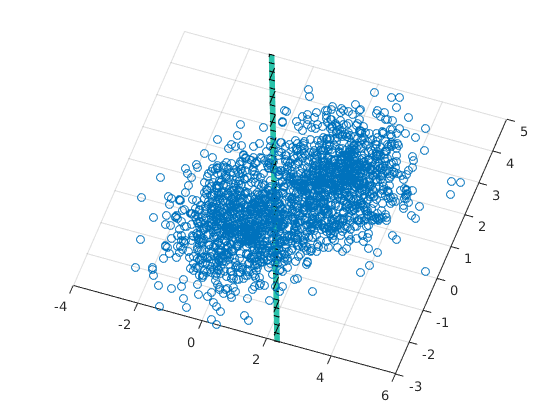

clf;
scatter3(X_test(:,1), X_test(:,2), y_test)
hold on
fsurf(@(x,y) nets{1}.iw{1,1}(1)*x + nets{1}.iw{1,1}(2)*y +  nets{1}.b{1})
zlim([0 1])




clf;

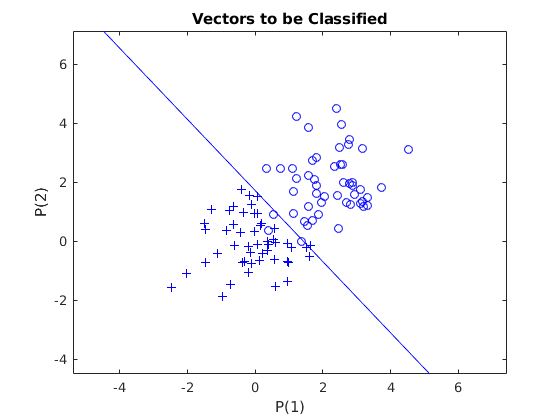


clf;

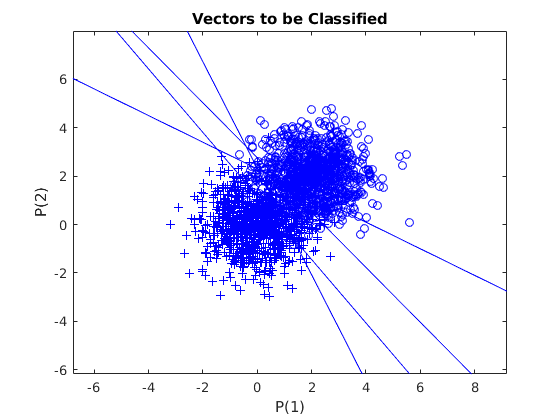

clf;
plotpv(X_test', y_test')
for i = 1:4

    plotpc(nets{i}.iw{1,1}, nets{i}.b{1})
    hold on
end

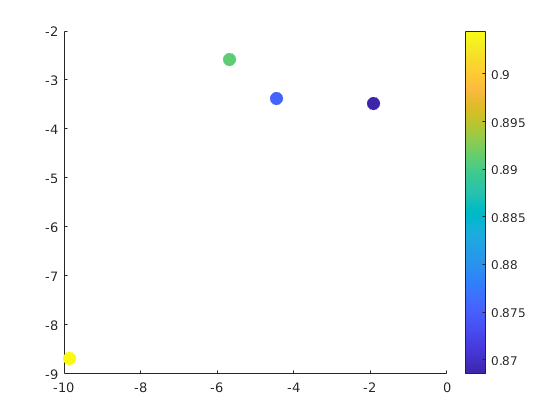

clf;
scatter(weights(:,1),weights(:,2), 100, accs, 'filled')
colorbar